clc
clear all

%adatok

dataSourceName='20170504_no1_laza';
data=importdata(strcat(strcat('measurementPoints/',dataSourceName),'.dat'));
t=data(:,1);                 %idő [s]
p_cuff=data(:,2);            %nyomás [bar]
U=data(:,3);                 %fesz [V]
delta_t=t(2)-t(1);
f_minta=1/delta_t;
f_nyq=f_minta/2

f_nyq = 2.3810e+03

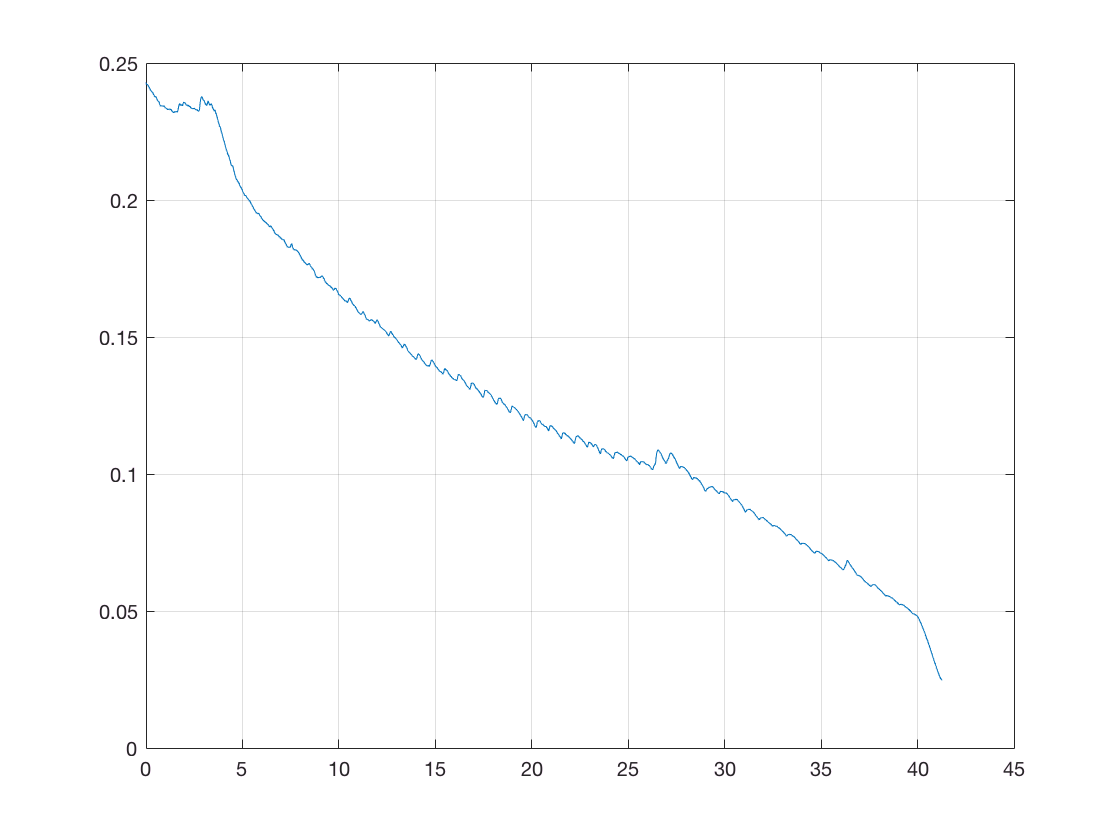


plot(t,p_cuff)
grid on;

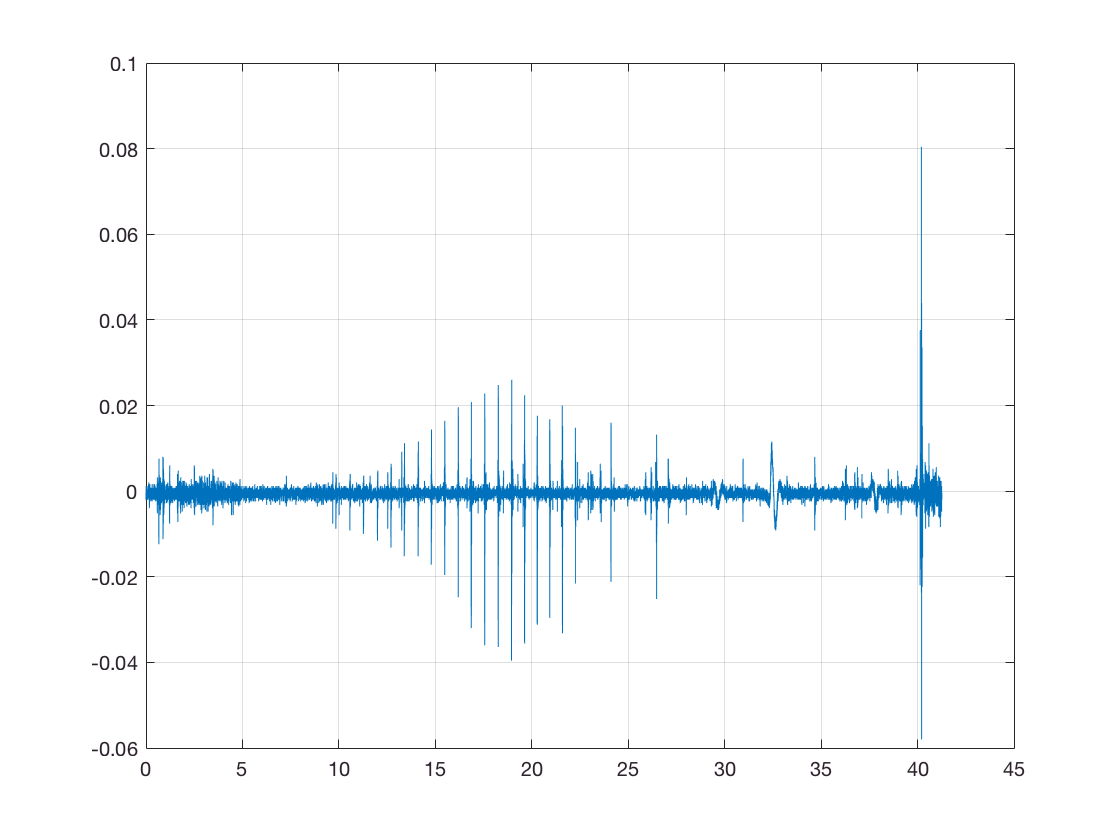


plot(t,U)
grid on;

p1=p_cuff;


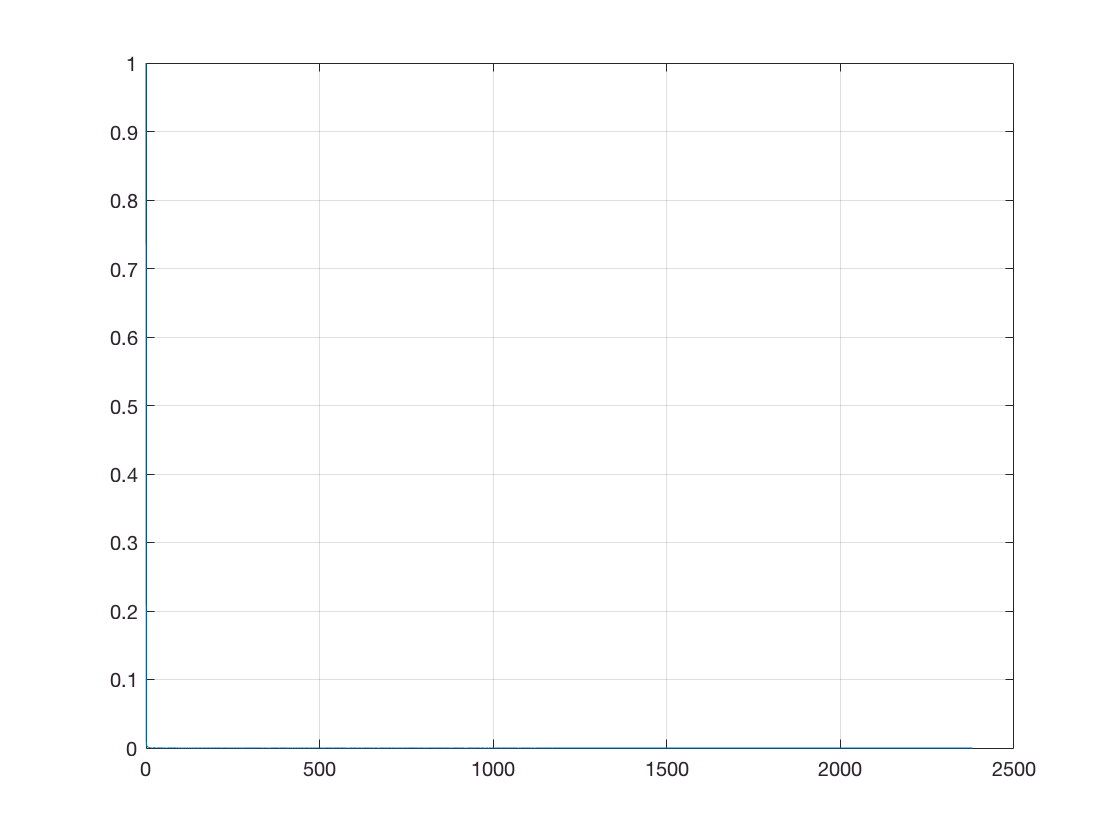

%fft
nfft=length(p1);                     %pontok száma
nfft2=2.^nextpow2(nfft);             %pontok száma 2 hatványaként
f_p1=fft(p1,nfft2);                  %jel frekvencia tartományban
f_p1=f_p1(1:nfft2/2);                %megfelezve
xfft=f_minta.*(0:nfft2/2-1)/nfft2;   %frekvencia skála

plot(xfft,abs(f_p1/max(f_p1)))
grid on;

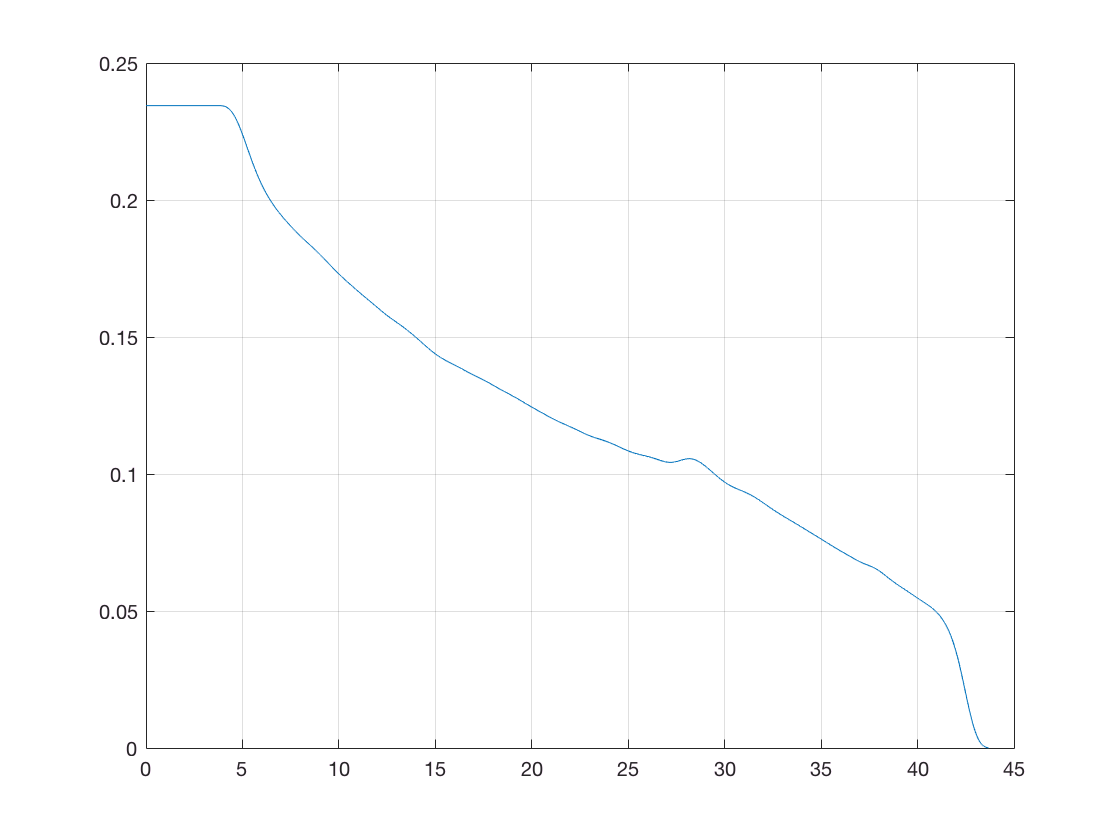

%low-pass szűrés
cut_off=1e-1/f_nyq;
order=10000;
h=fir1(order,cut_off);

p_o=conv(p1,h);
t_p_o=(0:length(p_o)-1)*delta_t;
t_p_o=t_p_o';

%% modifies lowpass first part
maxOfLowPass=max(p_o);
indexOfTheMaxElement=find(p_o==maxOfLowPass);
index = 1;
while index < indexOfTheMaxElement
    p_o(index)=maxOfLowPass;
    index=index+1;
end

plot(t_p_o,p_o)
grid on;

%high-pass szűrés
n=10000;
f=[0 1.2*pi/f_minta 12*pi/f_minta 1];
amp=[0 1 0];
up=[0.005 1.005 0.005];
lo=[-0.005 0.995 -0.005];
hh=fircls(n,f,amp,up,lo);
highpass_p1=conv(p1,hh);

%Korotkoff szűrés
n2=10000;
f2=[0 1.2*pi/f_minta 2*pi/f_minta 1];
amp2=[0 1 0];
up2=[0.005 1.005 0.005];
lo2=[-0.005 0.995 -0.005];
hh2=fircls(n2,f2,amp2,up2,lo2);
highpass_U=conv(U,hh2);

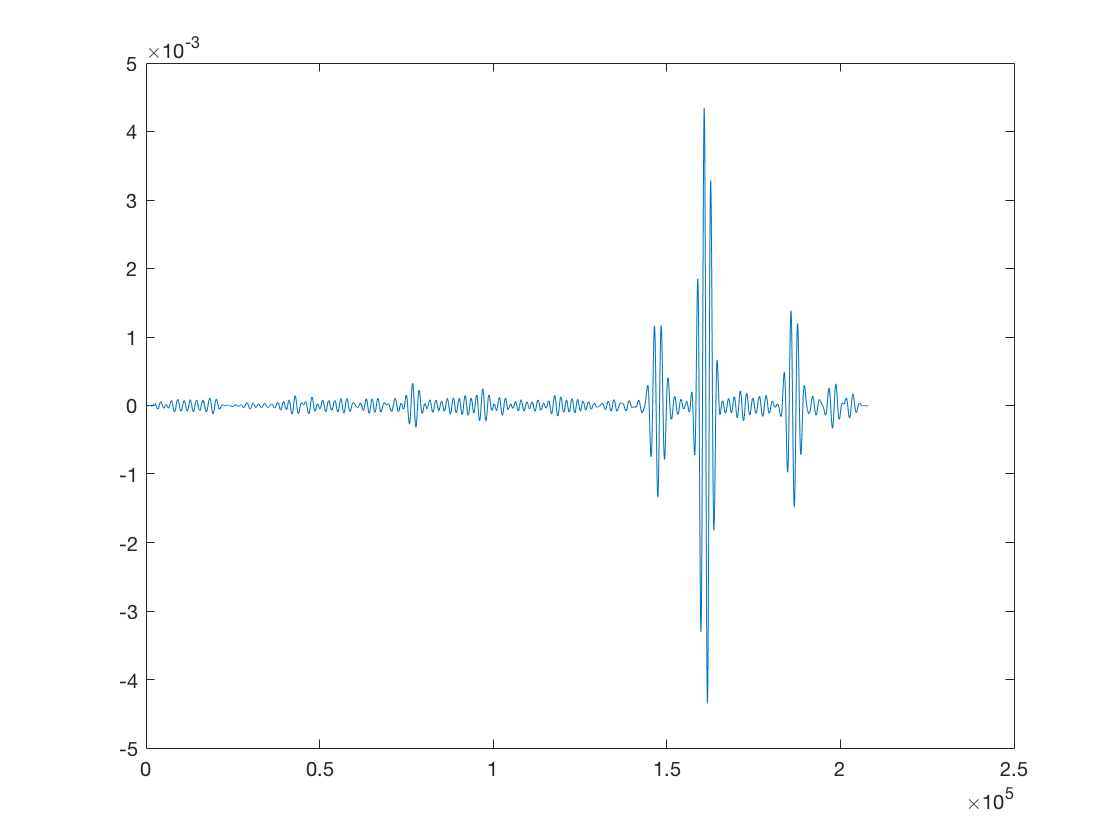

plot(highpass_U)

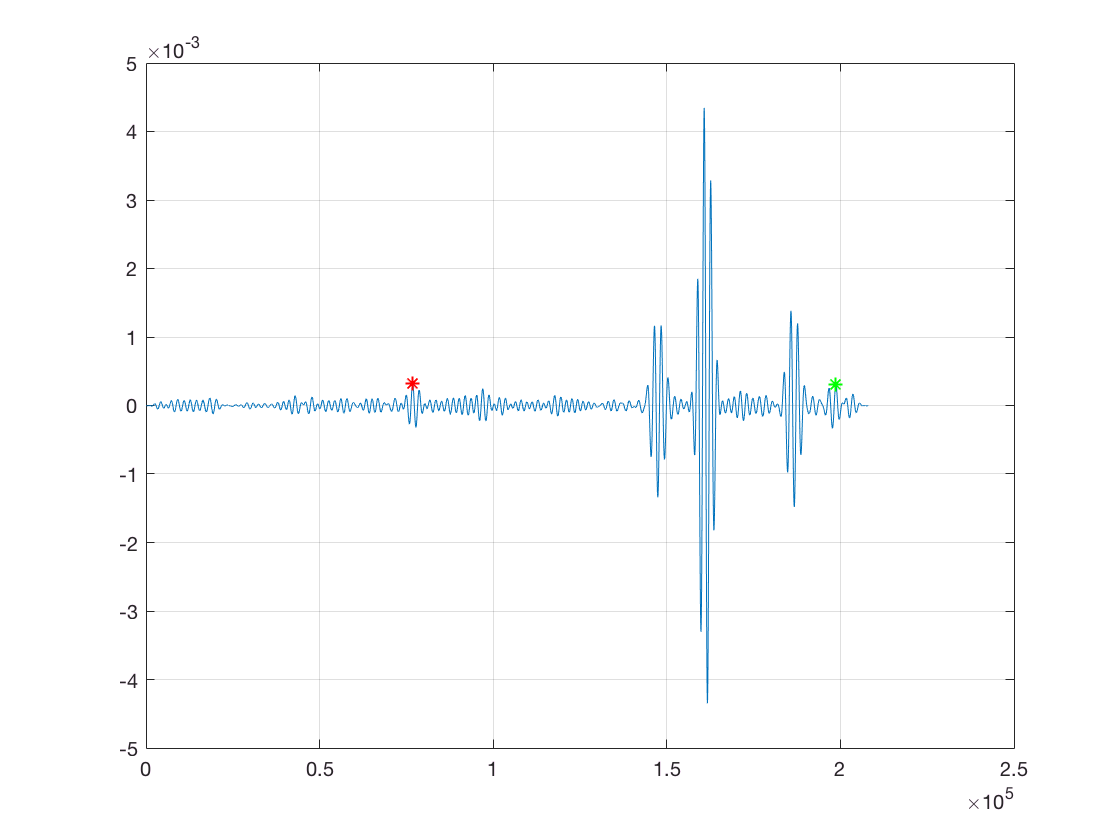

%Korotkoff-hang peak keresés
[pks,locs] = findpeaks(highpass_U,'MinPeakProminence',0.0003);
peaktimes=locs*delta_t;                 %a csúcsok helye időben

j=1;
while locs(j)<5e4
        j=j+1;                        
end

jj=length(locs);
while locs(jj)>2.2e5
    jj=jj-1;
end

syshely=locs(j);                       %az első csúcs helye
diashely=locs(jj);                     %az utolsó csúcs helye
tsys=peaktimes(j);                     %az első csúcs helye időben
tdias=peaktimes(jj);                   %az utolsó csúcs helye időben

plot(1:length(highpass_U),highpass_U,syshely,pks(j),'r *',diashely,pks(jj),'g *')
grid on;

%highpass_p1 peak keresés
[pks2,locs2] = findpeaks(highpass_p1,'MinPeakProminence',0.0011);
peaktimes2=locs2*delta_t;                 %a csúcsok helye időben

j2=1;
while locs2(j2)<5e4
        j2=j2+1;                        
end

jj2=length(locs2);
while locs2(jj2)>2e5
    jj2=jj2-1;
end

syshely2=locs2(j2);                       %az első csúcs helye
diashely2=locs2(jj2);                     %az utolsó csúcs helye
tsys2=peaktimes2(j2);                     %az első csúcs helye időben
tdias2=peaktimes2(jj2);                   %az utolsó csúcs helye időben

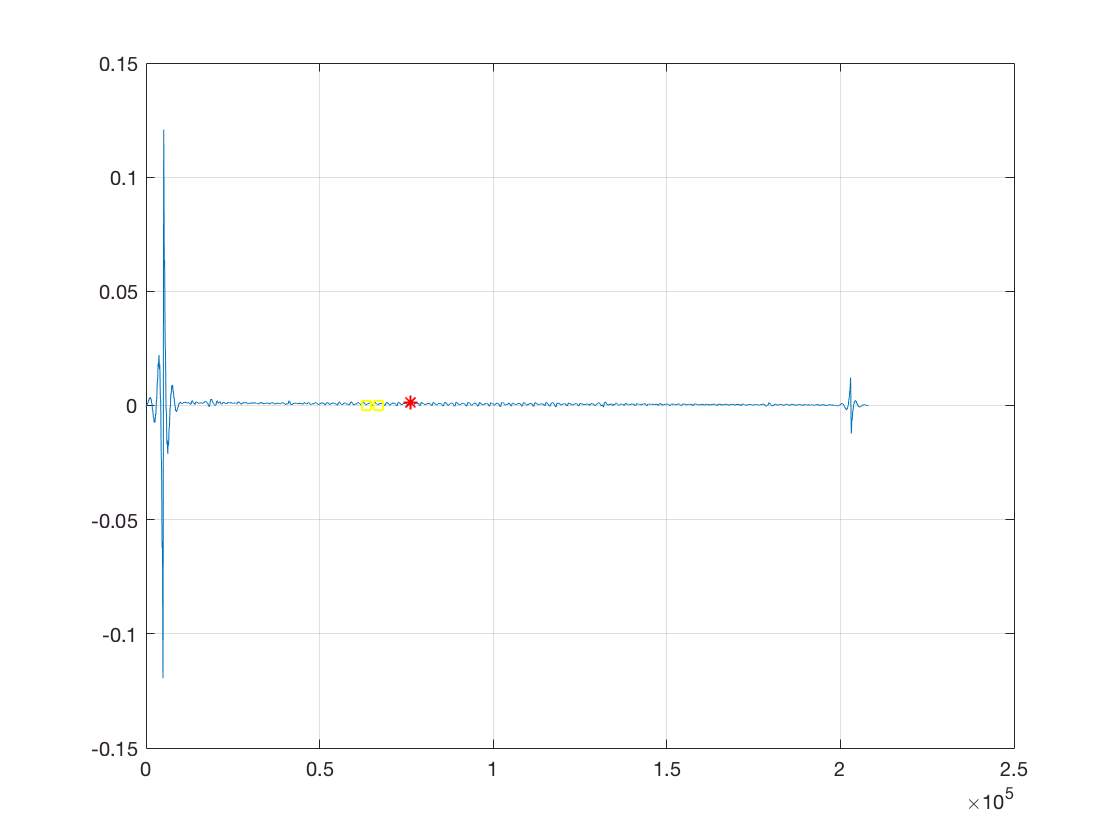

%peakek összehangolása
ertek=10e8;
for ii=1:length(locs2)
    if ertek>abs(syshely-locs2(ii))
        ertek=abs(syshely-locs2(ii));
        index=ii;
    end
end

period=locs2(index+1)-locs2(index);             

plot(1:length(highpass_p1),highpass_p1,locs2(index),pks2(index),'r *',syshely-4*period,0,'y s',syshely-3*period,0,'y s')     %a sárga körök jelölik a buckát, a piros csillagpedig az Korotkoff hang kezdetéhez legközelebbi peaket
grid on;

%p_i megalkotása
bucka=highpass_p1(locs2(index)-4*period:locs2(index)-3*period);     
pmax=max(bucka);                                %bar
szorzo=120*0.00133/pmax;                        %maximum 120 Hgmm-re szorzásához

szorzo = 1

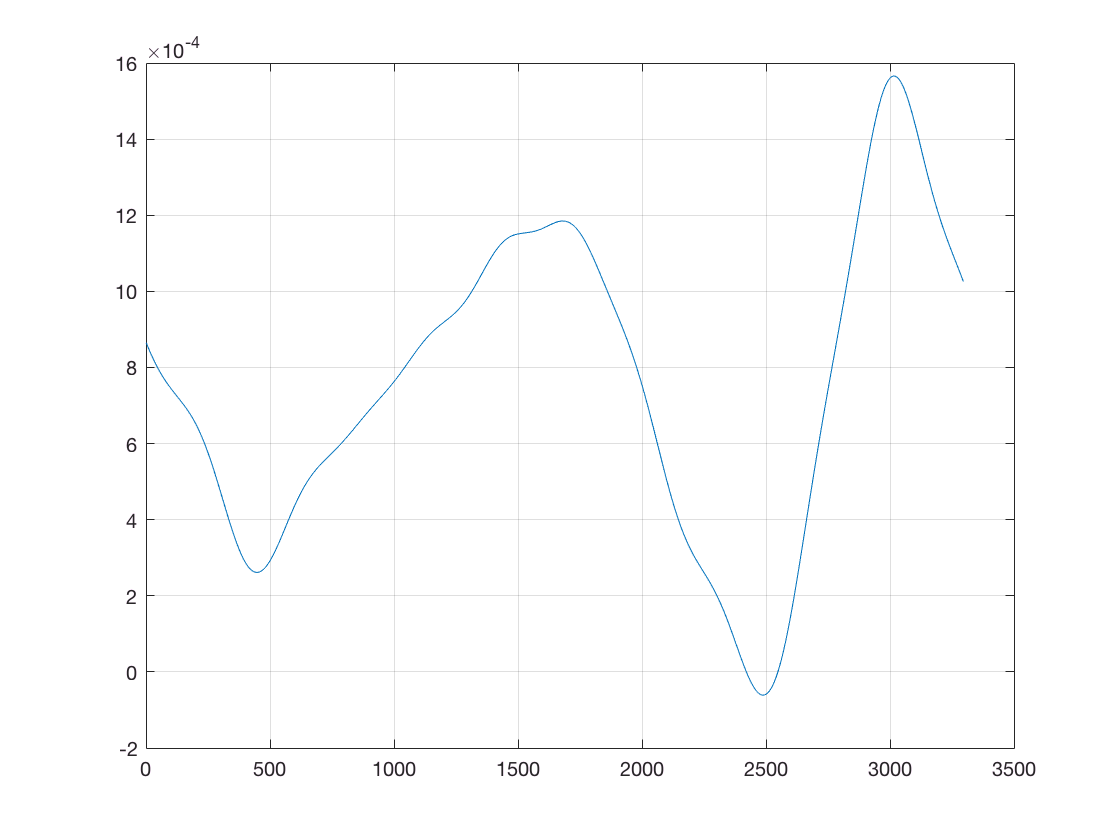

bucka_nagyitott=bucka*szorzo;

multiplier=ceil(length(t)/length(bucka));
t_p_i=(0:multiplier*length(bucka_nagyitott)-1)*delta_t;
p_i=zeros(1,multiplier*length(bucka));
for i=1:multiplier
p_i((i-1)*length(bucka)+1:i*length(bucka))=bucka_nagyitott;
end

plot(bucka_nagyitott)
grid on;

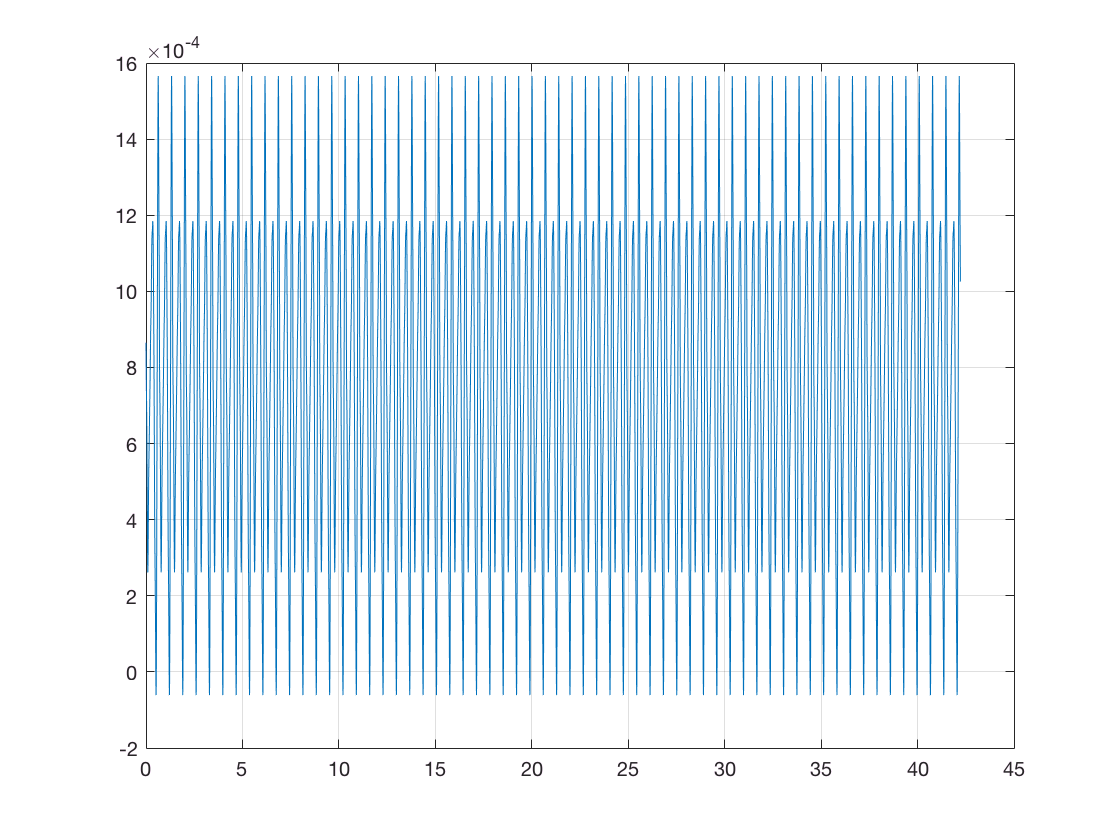

plot(t_p_i,p_i)
grid on;


t_p_o_name=strcat(strcat(dataSourceName,'-processed-'),'t_p_o.mat');
p_o_name=strcat(strcat(dataSourceName,'-processed-'),'p_o.mat');
t_p_i_name=strcat(strcat(dataSourceName,'-processed-'),'t_p_i.mat');
p_i_name=strcat(strcat(dataSourceName,'-processed-'),'p_i.mat');

%save(t_p_o_name,'t_p_o')
%save(p_o_name,'p_o')
%save(t_p_i_name,'t_p_i')
%save(p_i_name,'p_i')
